HW2

1) Total outcomes are $6*6=36$. There is only one way to roll snake eyes (a 1 and then a 1). There are many ways to roll a 7 (1 and 6, 2 and 5, 3 and 4) so rolling a 7 is much more probable. Probability is given by total ways per total outcomes, so for snake eyes it is 1/36 and for rolling a 7 we add up each way (including both "1 and 6" and "6 and 1") to get 6/36. The ratio of probabilities is then $\frac{\frac{6}{36}}{\frac{1}{36}}$ or 6 to 1.

2) Outcomes:

        for 2: (1 and 1) gives 1/36

        for 3: (1 and 2) (2 and 1) gives 2/36

        for 4: (2 and 2) (1 and 3) (3 and 1) gives 3/36

        for 5: (1 and 4) (4 and 1) (2 and 3) (3 and 2) gives 4/36

        for 6: (1 and 5) (5 and 1) (2 and 4) (4 and 2) (3 and 3) gives 5/36

        for 7: (1 and 6) (6 and 1) (2 and 5) (5 and 2) (3 and 4) (4 and 3) gives 6/36

        for 8: (2 and 6) (6 and 2) (3 and 5) (5 and 3) (4 and 4) gives 5/36

        for 9: (3 and 6) (6 and 3) (4 and 5) (5 and 4) gives 4/36

        for 10: (4 and 6) (6 and 4) (5 and 5) gives 3/36

        for 11: (5 and 6) (6 and 5) gives 2/36

        for 12: (6 and 6) gives 1/36

My code for $P_{A+B} \left(x\right)=\sum_z P_A \left(z\right)P_B \left(x-z\right)$

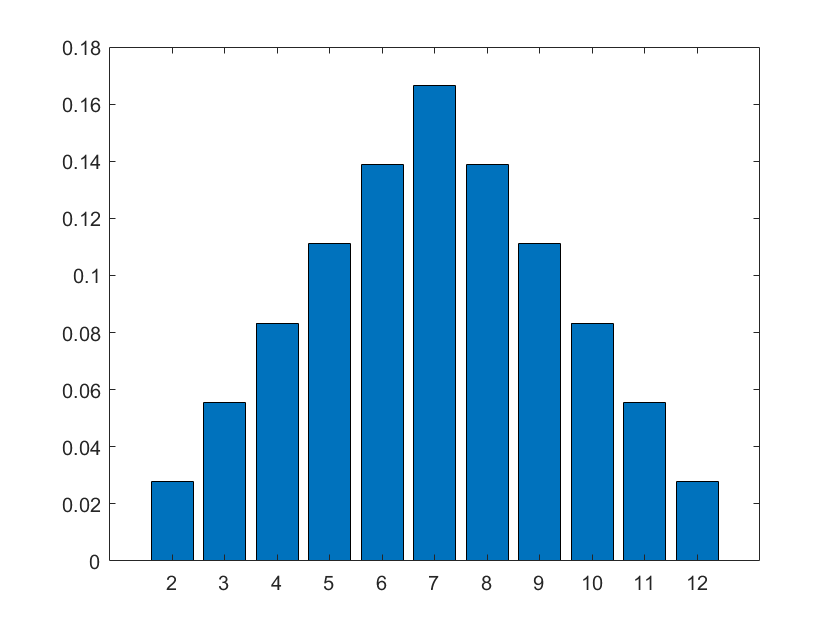

proba = 1/6;
probb = 1/6;
psum = 0;
y = [];
for x = [2:12]
    for z = [1:6]
        if (x - z > 0) && (x - z < 7)
            psum = psum + proba * probb;
        end         
    end
    y(x - 1) = psum;
    psum = 0;
end
bar([2:12],y);

disp(sum(y));

    1.0000



3) 

mu = dot([2:12],y); % calculating mean
disp(mu);

     7



vari = dot(([2:12] - mu).^2,y); % calculating variance
disp(vari);

    5.8333



4) It was a little unclear what average meant here. I'm assuming **average** here means convolutions with careful manipulation of the x-axis like we discussed in lecture. I believe this should follow the** average value of a dice in a roll** which would only range between **1 and 6** for any number of nice. I initially wrote this code to explore this interpretation:

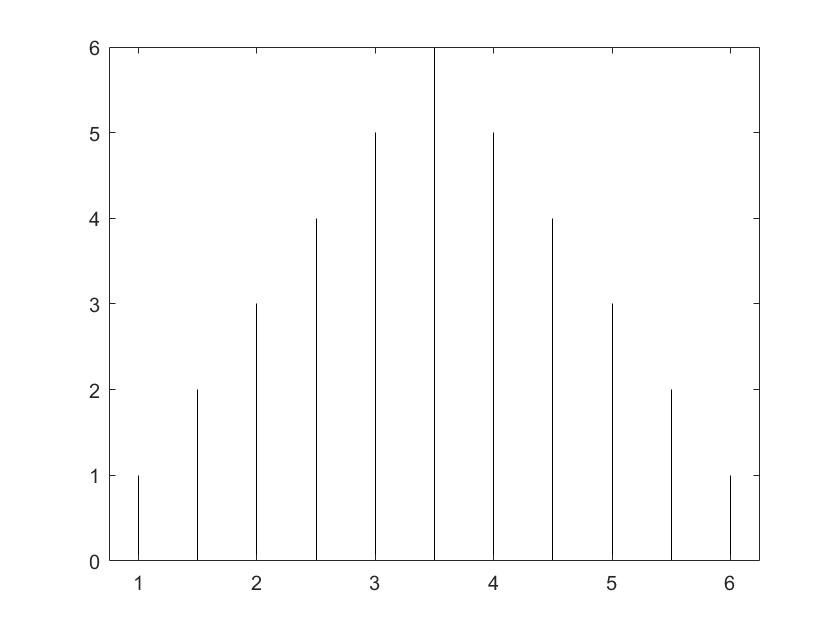

% not my complete answer for 4), just including here to show work
% average of n dice throws, ranging from 1 to 6. confirmed by hand to work
% for 2 dice, then generalized for many more.
clc; clear; close all;
start = [1,2,3,4,5,6];
dicethrown = 2; % 1 to 6 is OK
%totaloutcomes = 6 * dicethrown;
%dicethrown = 10; % far too much data to run quickly
for n = [1:(dicethrown - 1)]
    result = [];
    for x = [1:6]
        for k = start
            result = [result, (x + k)/2.0];
        end
    end
    start = result;
end
histogram(start,"BinWidth",0.0001); % small width to show discrete averages.

However, the results were not clear if it was becoming more Gaussian, in contradiction to problem 5). So I will instead use conv() and proceed as in 2).

I can just take the result of 2) and convolute again (and again and again and...) and divide the x-axis by the number of convolutions.

Instead of finding the sum of 2 dice, I find and graph the average of 10. Sum of 10 dice will range from 10 to 60.

% quick check of matlab documentation for convolutions
testv = [1,1,1,1,1,1]*(1/6);
q = conv(testv,testv,'full');
disp(q);

    0.0278    0.0556    0.0833    0.1111    0.1389    0.1667    0.1389    0.1111    0.0833    0.0556    0.0278



disp(sum(q));

    1.0000



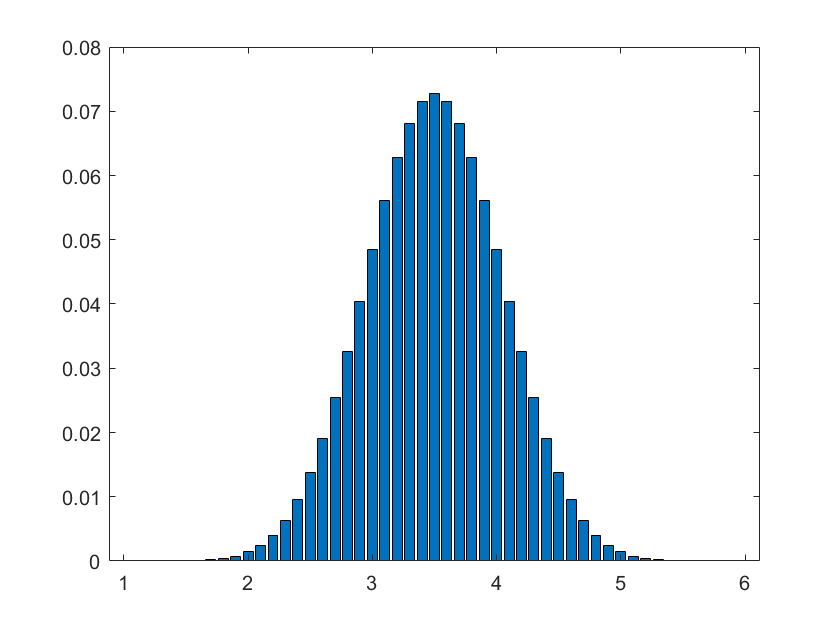

% seems to work, continuing on
for x = [3:10] % two calculated before this for q, convolute 8 more times.
    q = conv(q,testv);
end
x = [10:60];
xfix = [10:60]/10.0; % average
bar(xfix,q);

disp(sum(q));

    1.0000



Appears bell shaped. I'll check by plotting a normal distribution with the same mean and sigma.

bar(xfix,q);
hold on;
mu2 = dot(xfix,q); % calculating mean
disp(mu2);

    3.5000



vari2 = dot((xfix - mu2).^2,q); % calculating variance
disp(vari2);

    0.2917




belltest = makedist("Normal","mu",mu2,"sigma",sqrt(vari2));
y = pdf(belltest,xfix)/10.0; % average, normalized, sum was giving 10
plot(xfix,y,"LineWidth",2);
disp(sum(y));

    1.0000



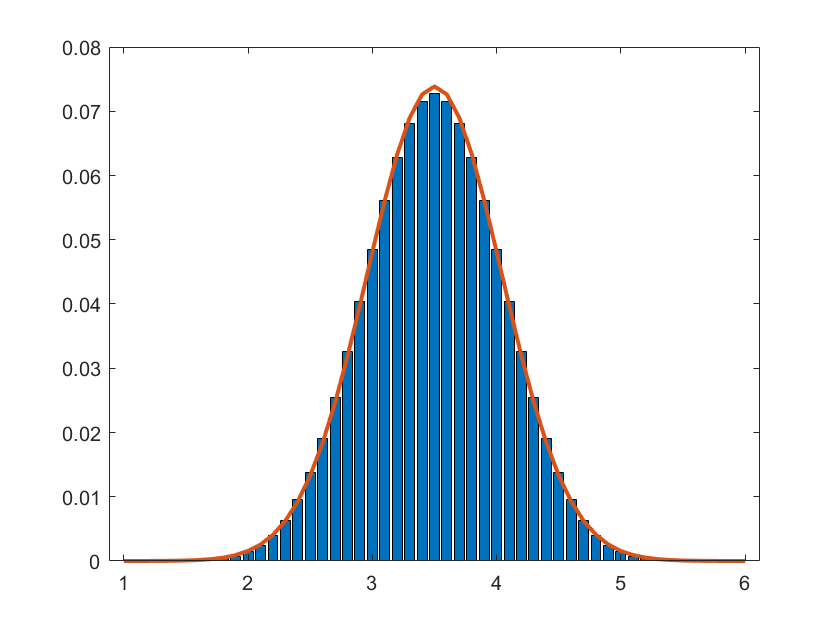

hold off;

Yes, this appears to be Gaussian, or at least tending to.

5) Showing that the sum and average of an initially Gaussian distribution is also Gaussian.

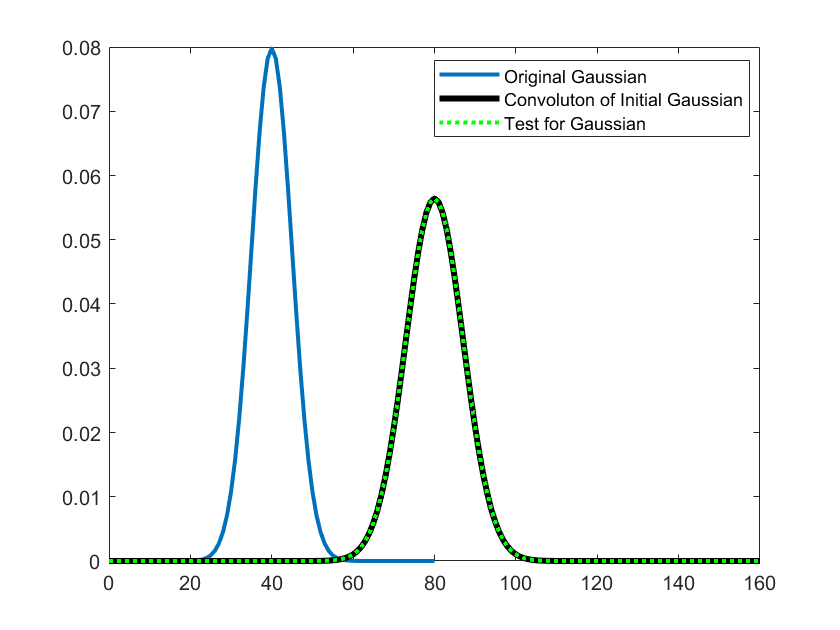

clc; clear; close all;
gaussdist = makedist("Normal","mu",40,"sigma",5);
x = [0:1:80];
initgauss = pdf(gaussdist,x);
convgauss = conv(initgauss,initgauss);
conx = [0:1:160];

% GRAPH OF SUM
plot(x,pdf(gaussdist,x),"LineWidth",2); % original gaussian
hold on;
plot(conx,convgauss,"LineWidth",3,"Color",'k'); % convolution, solid black line
% modeling convolution
mu3 = dot(conx,convgauss);
vari3 = dot((conx - mu3).^2,convgauss);
belltest3 = makedist("Normal","mu",mu3,"sigma",sqrt(vari3));
plot(conx,pdf(belltest3,conx),"Color",'g',"LineWidth",2,"LineStyle",":"); % spotted green line
legend("Original Gaussian","Convoluton of Initial Gaussian","Test for Gaussian","Location","best");
hold off;

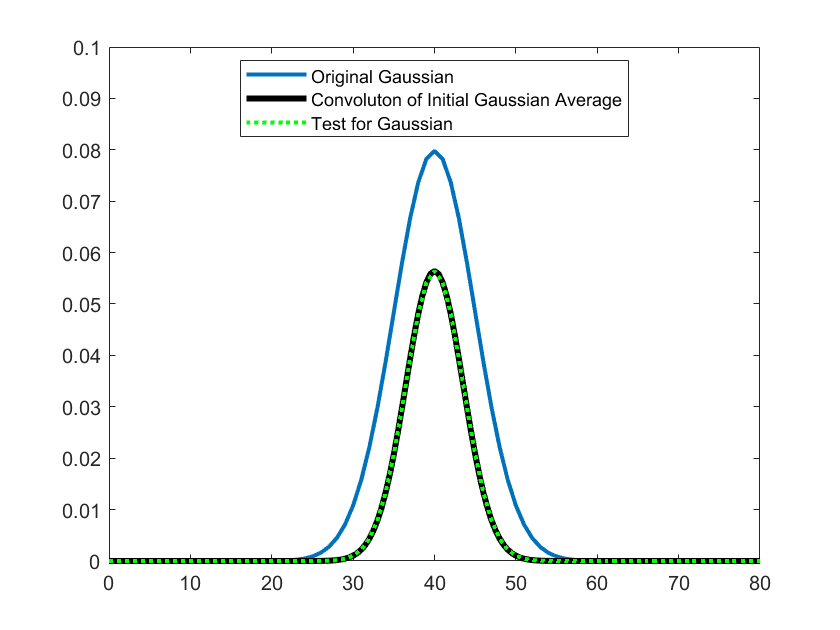


% GRAPH OF AVERAGE
plot(x,pdf(gaussdist,x),"LineWidth",2); % original gaussian
hold on;
fixconx = conx/2.0;
plot(fixconx,convgauss,"LineWidth",3,"Color",'k'); % convolution averaged, solid black line
% modeling averaged convolution
mu4 = dot(fixconx,convgauss);
vari4 = dot((fixconx - mu4).^2,convgauss);
belltest3 = makedist("Normal","mu",mu4,"sigma",sqrt(vari4));
plot(conx,pdf(belltest3,conx)/2.0,"Color",'g',"LineWidth",2,"LineStyle",":"); % spotted green line
legend("Original Gaussian","Convoluton of Initial Gaussian Average","Test for Gaussian","Location","best");
xlim([0,80]);
ylim([0,0.1]);

We see that they remain Gaussian. How did the standard deviation change for the sum and average?

% initially gaussian sigma is 5
disp(5)

     5



% after for sum is 
disp(sqrt(vari3));

    7.0711



% after for average is
disp(sqrt(vari4));

    3.5355



The standard deviation grew for the sum and shrunk for the average. When integrating a signal over time and averaging, we reduce the spread of the signal. In the case where we calculate sigma from the signal-free data, doing this procedure pulls the sides of the distribution in and reduces the odds that the random noise will produce something as signal-like as what we're looking for.